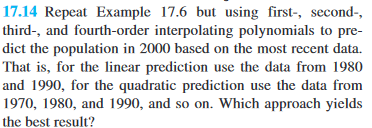

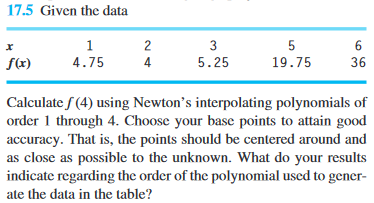

**Суть компиляции всех трех заданий:** смоделировать численность населения Земли в 2000 году, используя интерполяционные полиномы Лагранжа 1-й, 2-й, 3-й и 4-й степеней. Полиномы построить на данных 1990 и 1980 года для полинома 1-й степени, 1990, 1980, 1970 годов для 2-й и так далее.  

## Решение:

Данные о численности населения Земли в разные эпохи (Википедия; данные приведены в **тысячах** человек):

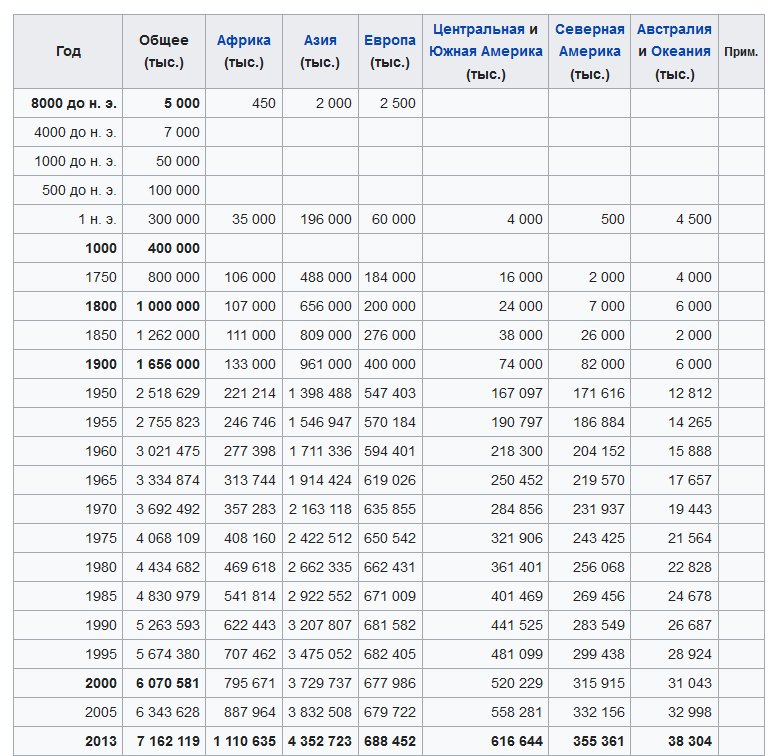

x_data = [1990 1980 1970 1960 1950];
fx = [5263593 4434682 3692492 3021475 2518629];%в тысячах человек
plot(x_data,fx, '*')
hold on
xlim([1945 1995])
ylim([2000000 6000000])
xlabel("Год");
ylabel("Численность населения Земли (в тыс. человек)");
title("Зависимость численности населения Земли от времени");
grid on

Интерполяционный полином Лагранжа ($n-\textrm{число}\;\textrm{"точек"}\;\textrm{данных}$):

$f_{n-1} \left(x\right)=\sum_{i=1}^n L_i \left(x\right)f\left(x_i \right)$, где $L_i \left(x\right)=\prod_{j=1,j\not= i}^n \frac{x-x_j }{x_i -x_j }$

**Полином первой степени (1990 и 1980 годы):**

format long
syms t;
polynom_1 = collect(Lagrange(x_data(1:2),fx(1:2),t))

$$polynom\_1 = \frac{828911\,t}{10}-159689696$$

plot(x_data,fx, '*')
xlim([1945 2005])
ylim([2000000 6500000])
xlabel("Год");
ylabel("Численность населения Земли (в тыс. человек)");
title("Полином Лагранжа первой степени");
hold on
fplot(polynom_1,'r');
grid on

Смоделированная численность населения в 2000 году (в тыс. человек):

population_1 = Lagrange(x_data(1:2),fx(1:2),2000)

population_1 =      6092504


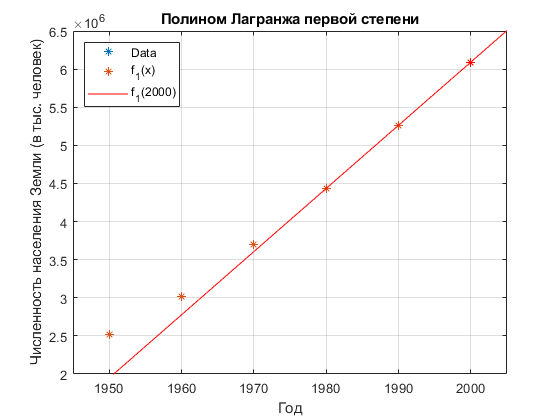

plot(2000,population_1,'r*')
legend({'Data','f_1(x)','f_1(2000)'},'Location','northwest')
hold off

**Полином второй степени (1990, 1980 и 1970 годы):**

polynom_2 = collect(Lagrange(x_data(1:3),fx(1:3),t))

$$polynom\_2 = \frac{86721\,t^{2}}{200}-\frac{6554083\,t}{4}+1548800725$$

Смоделированная численность населения в 2000 году (в тыс. человек):

population_2 = Lagrange(x_data(1:3),fx(1:3),2000)

population_2 =      6179225


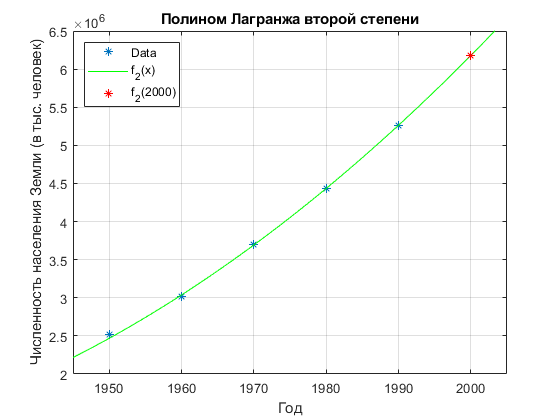

plot(x_data,fx, '*')
xlim([1945 2005])
ylim([2000000 6500000])
xlabel("Год");
ylabel("Численность населения Земли (в тыс. человек)");
title("Полином Лагранжа второй степени");
hold on
grid on
fplot(polynom_2,'g');
plot(2000,population_2,'r*')
legend({'Data','f_2(x)','f_2(2000)'},'Location','northwest')
hold off

**Полином третьей степени (1990, 1980, 1970 и 1960 годы):**

polynom_3 = collect(Lagrange(x_data(1:4),fx(1:4),t))

$$polynom\_3 = \frac{3887\,t^{3}}{1500}-\frac{2991783\,t^{2}}{200}+\frac{1730304583\,t}{60}-18565631327$$

Смоделированная численность населения в 2000 году (в тыс. человек):

population_3 = Lagrange(x_data(1:4),fx(1:4),2000)

population_3 =      6194773


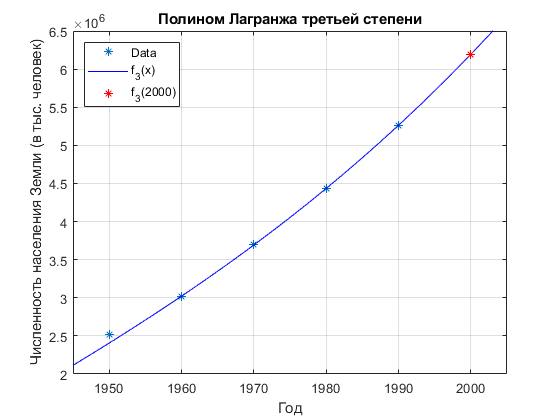

plot(x_data,fx, '*')
xlim([1945 2005])
ylim([2000000 6500000])
xlabel("Год");
ylabel("Численность населения Земли (в тыс. человек)");
title("Полином Лагранжа третьей степени");
hold on
grid on
fplot(polynom_3,'b');
plot(2000,population_3,'r*')
legend({'Data','f_3(x)','f_3(2000)'},'Location','northwest')
hold off

**Полином четвертой степени (1990, 1980, 1970, 1960 и 1950 годы):**

polynom_4 = collect(Lagrange(x_data,fx,t))

$$polynom\_4 = \frac{56273\,t^{4}}{120000}-\frac{22212287\,t^{3}}{6000}+\frac{13151900857\,t^{2}}{1200}-\frac{216316599898\,t}{15}+7115866103719$$

Смоделированная численность населения в 2000 году (в тыс. человек):

population_4 = Lagrange(x_data(1:5),fx(1:5),2000)

population_4 =      6307319


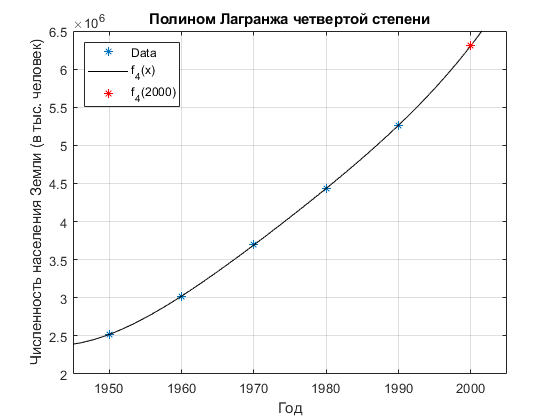

plot(x_data,fx, '*')
xlim([1945 2005])
ylim([2000000 6500000])
xlabel("Год");
ylabel("Численность населения Земли (в тыс. человек)");
title("Полином Лагранжа четвертой степени");
hold on
grid on
fplot(polynom_4,'k');
plot(2000,population_4,'r*')
legend({'Data','f_4(x)','f_4(2000)'},'Location','northwest')
hold off

function yint = Lagrange(x,y,xx)
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
s = 0;
for i = 1:n 
    product = y(i);  
    for j = 1:n    
        if i ~= j      
            product = product*(xx-x(j))/(x(i)-x(j));
        end  
    end  
    s = s+product;
end
yint = s;
end

Как можно видеть из данных Википедии, реальная численность населения Земли в 2000 году - 6 070 581 тысяч человек.

Самый близкий к реальному результат (6 092 504 тыс. человек) дает полином первой степени, построенный только на данных 1990 и 1980 годов, наиболее близких к исследуемому 2000 году и, соответственно, не искажающих актуальные данные устаревшими тенденциями изменения численности населения.